## Genetic Algorithm Optimization for the Generator


Multi-objective optimization:
2 Variables
1 Integer variables

Options:
CreationFcn:       @gacreationsobol
CrossoverFcn:      @crossoverintermediate
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                              Average            Average
Generation   Func-count    Pareto distance    Pareto spread
    1            10                 1                 1
    2            20         0.0303677         0.0888687
    3            30         0.0866163          0.262078
    4            40         0.0666125          0.426344
    5            50         0.0207653         0.0611375
    6            60         0.0290518         0.0800497
    7            70         0.0449956          0.124502
    8            80         0.0193669         0.0455391
    9            90         0.0796499          0.142582
   10           100         0.0144715         0.0354134
   11           110        0.00496021          0.999998
   12           120         0.0417752    

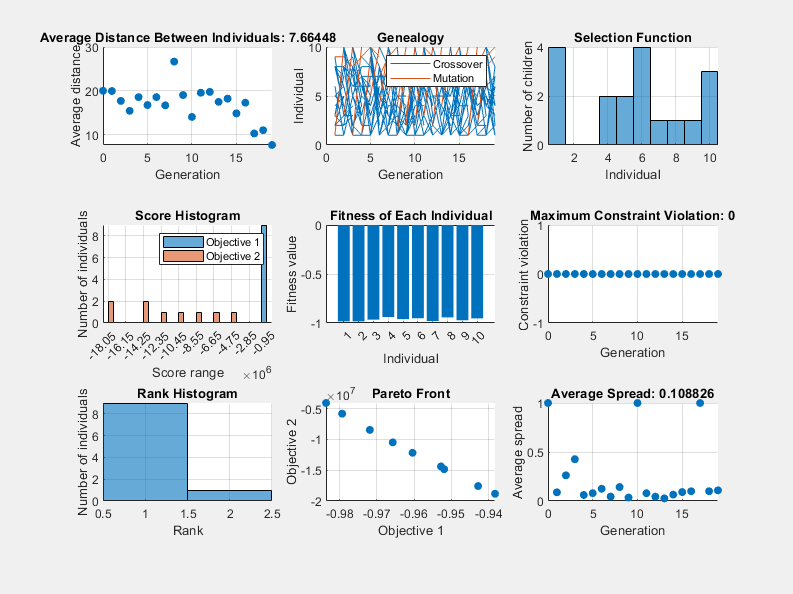

% Set nondefault solver options
options = optimoptions("gamultiobj","PopulationSize",10,"MaxGenerations",20,...
    "UseParallel",true,"ConstraintTolerance",1,"Display","iter","PlotFcn",...
    ["gaplotdistance","gaplotgenealogy","gaplotselection",...
    "gaplotscorediversity","gaplotscores","gaplotmaxconstr","gaplotrankhist",...
    "gaplotpareto","gaplotspread"]);

% Solve
[solution,objectiveValue] = gamultiobj(@optimization_cost,number_of_inputs,...
    [],[],[],[],lower_bounds,upper_bounds,[],IntCon,options);


% Clear variables
clearvars options